# The Jacobi and Gauss-Seidel Methods

by Dan Ellison and DJ Poulin

## What is an iterative method?

Much of linear algebra is dedicated to solving linear systems, $$A\vec{x} = \vec{b}$$, for the vector $$\vec{x}$$. In an intro Linear Algebra course, students solve relatively small matrices, whose dimensions are generally smaller than 5, with Gaussian Elimination (GE). You might have noticed that this process takes a fair amount of time. Imagine trying to use GE to solve a system with 1000 variables! When we have to deal with such systems, it would be beneficial if we could use a computer to calculate $\vec{x}$ for us. Yet even a computer will take prohibitively long amounts of time to solve matrices as they grow to sizes in the thousands. As such, many methods have been developed for the sake of solving linear systems more quickly, including iterative methods.

Iterative methods provide an efficient alternative to direct methods for solving the linear system $$A\vec{x}=\vec{b}$ for $\vec{x}$$. Essentially, in an iterative method, we guess a solution and then progressively improve it, as opposed to solving the system directly. In practice, iterative methods are created by splitting $$A$$ into separate matrices, for example, $A = S - T$, and then solving the resulting equation for the next iteration. While there are infinitely many ways to split $$A$
$, only certain ones help us approximate the true value of x. Two such iterative techniques are the Jacobi and the Gauss-Seidel methods.

## The Jacobi Method

 In the Jacobi Method, we start with a guess of $\vec{x}$ (usually the zero vector), and then plugging our guesses into our linear system for all but the first variable in the first equation, all but the second in the second equation, and so on. We then compute the new value of each variable by solving each of the equations for the now single unknown. In practive, this involves splitting $$A$$ into $$D-T$$, where $$D$$ is the diagonal component of $$A$$. We will discuss this matrix notation shortly, but first, let's look under the hood at what is actually going on during each iteration.

For an $$n\times n$ matrix $A$$ we can describe this iterative improvement as [2]

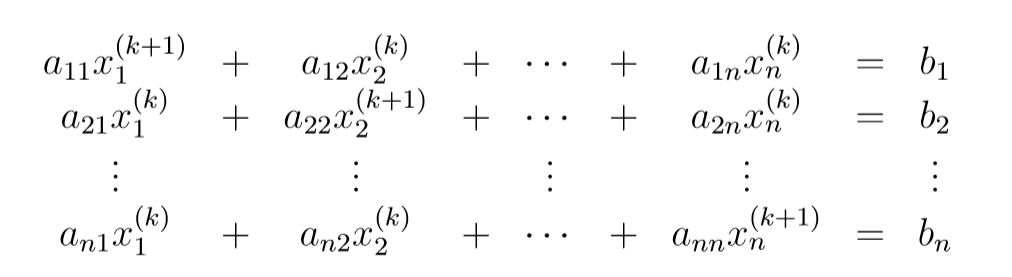,

where the $$x^{(k+1)}$$ terms will become our improved guess values, and the $$x^{(k)}$$ terms are our current iteration's guesses. We can thus solve for the $$x^{(k+1)}$$ terms as all other terms are known (either constants like $$b$
$ or our current guess values $$x^{(k)}$$. Below, we show the first two iterations of the Jacobi method for an example linear system, namely

$A= \left[\matrix{ 7 & 1 & 3 &2 \cr 2 & 5 & 1 & 1 \cr 4 & 3 &10 & 2 \cr 1 & 8 & 2 & 12} \right]$, $b = \left[\matrix{ 6 \cr -4 \cr 15 \cr -39} \right]$,$\vec{x}^{(0)}= \left[\matrix{ 0 \cr 0 \cr 0 \cr 0} \right]$.

Before going any further, we should also clearly outline the notation we plan to use. Superscript will reference the iteration we are currently on. On this live script, super script will **never **represent an exponent. For an example, as you can see above, our starting guess for$\vec{x}$ is written as$\vec{x}^{(0)}$. If we wanted to refer to a general iteration, we would write $\vec{x}^{(k)}$. If there is any subscript, it will represent which element of the vector we are referring to. For instance, if we wanted to reference the first element of $\vec{x}^{(0)}$, we would write ${x}^{(0)}_1$. It should also be noted that this system is much simpler and smaller than the complex and large matrices for which algorithms like the Jacobi method were developed; as such, we could actually use GE on this matrix without expecting a huge runtime. However, it is much easier to explain how the Jacobi method works by applying it to a small system such as this. We will now do just that.

For the first equation (first row), we want to solve for the first element of $\vec{x}^{(1)}$, namely $x^{(1)}_1$.  So we solve $7x^{(1)}_1 + 1x^{(0)}_2 + 3x^{(0)}_3 + 2x^{(0)}_4 = b_{1}$. Plugging in our example. we have $7x^{(1)}_1 + 0 + 0 + 0 = 6$. So $x^{(1)}_1 = \frac{6}{7}.$  The other 3 equations are written below.


$$2x^{(0)}_1 + 5x^{(1)}_2 + 1x^{(0)}_3 + 1^{(0)}_4 = b_{2}$$



$$2(0) + 5x^{(1)}_2 + 1(0) + 1(0) = -4$$



$$x^{(1)}_2 = \frac{-4}{5}$$



$$4x^{(0)}_1 + 3x^{(0)}_2 + 10x^{(1)}_3 + 2x^{(0)}_4 = b_{3}$$



$$4(0) + 3(0) + 10x^{(1)}_3 + 2(0) = 15$$



$$x^{(3)}_1 = \frac{15}{10}$$



$$1x^{(0)}_1 + 8x^{(0)}_2 + 2x^{(0)}_3 + 12x^{(1)}_4 = b_{4}$$



$$1(0) + 8(0) + 2(0) + 12x^{(1)}_4 = -39$$



$$x^{(4)}_1 = \frac{-39}{12}$$


Because our initial guess was the zero vector, the first iteration was relatively simple to calculate. If you run the following code, it will compute the first iteration of the same system. If you are interested in the code behind the myJacobi() function, you can find it in the appendix. 

%These first two lines initialize A and b.
A = [7 1 3 2; 2 5 1 1; 4 3 10 2; 1 8 2 12];
b = [6; -4; 15; -39];
%This next line is another way of solving for x. The details are not
%important, but it, too, is slower the the Jacobi method.
xTRUE = A\b;
%We will use the zero vector as our starting guess
x0 = zeros(4,1);
%Because the Jacobi Method likely won't give us an exact answer, we need to
%specify how close we want to get. We measure this via the relative
%residual, an alternative to relative error that does not require us to
%know the true solution to calculate.
tol = 10^-8;
%Because we only want to calculate the first iterate, we set the max number
%of iterations to 1
itMax = 1;
%Here, we compute the first Jacobi iteration
[~, firstIteration, ~] = myJacobi(A,b,x0,tol,itMax)

firstIteration =     0.8571
   -0.8000
    1.5000
   -3.2500


With $\vec{x}^{(1)}= \left[\matrix{ 0.8571 \cr -0.8 \cr 1.5 \cr -3.25} \right]$, we can now compute the second iteration.


$$2x^{(2)}_1 + 5x^{(1)}_2 + 1x^{(1)}_3 + 1x^{(1)}_4 = b_{1}$$



$$2x^{(2)}_{1} + 5(-0.8) + 1(1.5) + 1(-3.25) = 6$$



$$x^{(2)}_1 = 1.2571$$



$$2x^{(1)}_1 + 5x^{(2)}_2 + 1x^{(1)}_3 + 1^{(1)}_4 = b_{2}$$



$$2(0.8571) + 5x^{(2)}_2 + 1(1.5) + 1(-3.25) = -4$$



$$x^{(2)}_2 = -0.7929$$



$$4x^{(1)}_1 + 3x^{(1)}_2 + 10x^{(2)}_3 + 2x^{(1)}_4 = b_{3}$$



$$2(0.8571) + 5(-0.8) + 1x^{(2)}_3 + 1(-3.25) = 15$$



$$x^{(2)}_3 = 2.0471$$



$$1x^{(1)}_1 + 8x^{(1)}_2 + 2x^{(1)}_3 + 12x^{(2)}_4 = b_{4}$$



$$2(0.8571) + 5(-0.8) + 1(1.5) + 1x^{(2)}_4 = -39$$



$$x^{(2)}_4 = -3.0381$$


So $\vec{x}^{(2)}= \left[\matrix{ 1.2571 \cr -0.7929 \cr 2.0471 \cr -3.0381} \right]$. Again, you can run the following code to check our solution.

A = [7 1 3 2; 2 5 1 1; 4 3 10 2; 1 8 2 12];
b = [6; -4; 15; -39];
xTRUE = A\b;
x0 = zeros(4,1);
tol = 10^-8;

itMax = 2;
[~, secondJacobiIteration, ~] = myJacobi(A,b,x0,tol,itMax)

secondJacobiIteration =     1.2571
   -0.7929
    2.0471
   -3.0381


Recall that we earlier mentioned splitting $A$ into $D$ and $T$, where $D$ is a matrix with only the diagonal elements of $A$, and $T$ is a matrix with only the nondiagonal elements of $A$. After seeing these two iterations, you might be wondering why we bothered calculating the matrices $T$ and $D$ in the first place. That's because we can use $T$ and $D$ to more concisely caclulate each iteration. Consider the equation$$$x^{(k+1)}=D^{-1}\left[b-(L+U)x^{(k)}\right].$$$ Note that $L$ is the matrix with the nondiagonal elements of $A$ that are below the diagonal, and that $U$is the matrix with the nondiagonal elements of $A$ that are above the diagonal. Then $L + U = T$. This equation is the same as the equations we went through individually above. It might be easier to see this by multiplying both sides by $D$ on the left and examing the resulting equation, $$$Dx^{(k+1)}=\left[b-(L+U)x^{(k)}\right]$$$. On the left we have

$Dx^{(k+1)}=$$ \left[\matrix{ 7 & 0 & 0 &0 \cr 0 & 5 & 0 & 0 \cr 0 & 0 &10 & 0 \cr 0 & 0 & 0 & 12} \right]  \cdot$$\left[\matrix{ x^{(k+1)}_1 \cr x^{(k+1)}_2 \cr x^{(k+1)}_3 \cr x^{(k+1)}_4} \right]$$= \left[\matrix{ 7x^{(k+1)}_1 \cr 5x^{(k+1)}_2 \cr 10x^{(k+1)}_3 \cr 12x^{(k+1)}_4} \right]$,

and on the right,

$\left[b-(L+U)x^{(k)}\right]$$ = \left[\matrix{ 6 \cr -4 \cr 15 \cr -39} \right]$$- \left[\matrix{ 0 & 1 & 3 &2 \cr 2 & 0 & 1 & 1 \cr 4 & 3 &0 & 2 \cr 1 & 8 & 2 & 0} \right]$$\cdot \left[\matrix{ x^{(k)}_1 \cr x^{(k)}_2 \cr x^{(k)}_3 \cr x^{(k)}_4} \right]$$ = \left[\matrix{ 6 \cr -4 \cr 15 \cr -39} \right]$$- \left[\matrix{ 0x^{(k)}_1 & 1x^{(k)}_2 & 3x^{(k)}_3 &2x^{(k)}_4 \cr 2x^{(k)}_1 & 0x^{(k)}_2 & 1x^{(k)}_3 & 1x^{(k)}_4 \cr 4x^{(k)}_1 & 3x^{(k)}_2 &0x^{(k)}_3 & 2x^{(k)}_4 \cr 1x^{(k)}_1 & 8x^{(k)}_2 & 2x^{(k)}_3 & 0x^{(k)}_4} \right]$. 

So $$$Dx^{(k+1)}=\left[b-(L+U)x^{(k)}\right]$$$ is equivalent to 

$\left[\matrix{ 7x^{(k+1)}_1 \cr 5x^{(k+1)}_2 \cr 10x^{(k+1)}_3 \cr 12x^{(k+1)}_4} \right]$$ = \left[\matrix{ 6 \cr -4 \cr 15 \cr -39} \right]$$- \left[\matrix{ 0x^{(k)}_1 & 1x^{(k)}_2 & 3x^{(k)}_3 &2x^{(k)}_4 \cr 2x^{(k)}_1 & 0x^{(k)}_2 & 1x^{(k)}_3 & 1x^{(k)}_4 \cr 4x^{(k)}_1 & 3x^{(k)}_2 &0x^{(k)}_3 & 2x^{(k)}_4 \cr 1x^{(k)}_1 & 8x^{(k)}_2 & 2x^{(k)}_3 & 0x^{(k)}_4} \right]$. 

You can see that each row is one of the equations from above. From now on, we will be using this matrix notation when we apply and implement the Jacobi Method. If you would like to see subsequent iterations, adjusting the slider below will calculate $\vec{x}^{(k)}$. Note that the true solution for this system is $\left[\matrix{ 1 \cr -1 \cr 2 \cr -3} \right]$, and that after 56 iterations, we have gotten so close to the true solution that further iterations wouldn't show up below.

k = 56

k = 56

A = [7 1 3 2; 2 5 1 1; 4 3 10 2; 1 8 2 12];
b = [6; -4; 15; -39];
x0 = [0; 0; 0; 0];
tol = 10^-8;
[~,xGuess,~, ~] = myJacobi(A,b,x0,tol,k)

xGuess =     1.0000
   -1.0000
    2.0000
   -3.0000


##  The Gauss-Seidel Method

The Gauss-Seidel method (GS method) improves on the Jacobi method by using the updated guess values as we go down the equations. It is therefore similar to the Jacobi method, so we will describe it more briefly (if you are interest in a more in depth explanation of the Gauss-Seidel method, take a look at [2]**, **which we paraphrase and elaborate on here). For instance, after we solve the first equation we have a value for $$x_1^{(k+1)}$$ we can use in the following equations instead of the $$x_1^{(k)}$$ we continued using in the Jacobi method. The same is true for the $$x_2^{(K+1)}$$ value after solving the second and so on. We can thus rewrite our iterative improvement in terms of linear equations as [2]:

$$$
    a_{11}x_1^{(k+1)}  + a_{12}x_2^{(k)} + \cdots +a_{1n}x_n^{(k)} = b_1\\
    a_{21}x_1^{(k+1)} + a_{22}x_2^{(k+1)} + \cdots + a_{2n}x_n^{(k)} = b_2\\
    \ \vdots \ \ \ \ \ \ \ \ \vdots \ \ \ \ \ \ \ \ \ \ \ \ \vdots  \ \ \ \ \ \vdots\\
    a_{n1}x_1^{(k+1)} + a_{n2}x_2^{(k+1)} + \cdots + a_{nn}x_n^{(k+1)} = b_n
$$$ .

Once again we set the initial guess to be the zero vector. Isolating the $$(k+1)$$ terms, we have

    $x_i^{(k+1)} = $$\frac{b_i-\sum\limits_{j=1}^{i-1}a_{ij}x_j^{(k+1)}-\sum\limits_{j=i+1}^{n}a_{ij}x_j^{(k)}}{a_{ii}}$.

To put this equation into simpler terms, consider the second row. We are solving for $$x_2{(k+1)}$$. Then we subtract the other terms from both sides and then dividing by $a_{22}$. Then we have $x_i^{(k+1)} = \frac{b_2 - a_{21}x_1^{(k+1)} - a_{23}x_3^{(k)} - a_{24}x_4^{(k)}}{a_{22}}$ $= \frac{b_2-\sum\limits_{j=1}^{1}a_{2j}x_j^{(k+1)}-\sum\limits_{j=3}^{4}a_{2j}x_2^{(k)}}{a_{ii}}$.

You might notice that this method is quite similar to the Jacobi method, apart from a few key differences. In the Jacobi method, we could solve the for each $$x_i^{(k+1)}$$ in whatever order we wanted. Now, for the Gauss-Seidel method, we must solve for each $$x_i^{(k+1)}$$ sequentially, as we need knowledge of previous $$x_i^{(k+1)}$$ values to do so. The matrix form of Gauss-Seidel is also a bit different. Consider the equations

$L+D+U = A$ and

$(L+D+U)\vec{x}  =\vec{b}$.

In the Gauss Seidel method, we still multiply the strictly upper triangular part of A (which is equal to U) by $\vec{x}^{(k)}$. However, instead of multiplying the strictly lower triangular part of $A$ (which is equal to $L$) by $\vec{x}^{(k+1)}$. Then we are solving 


$$Lx^{(k+1)}+Dx^{(k+1)}+Ux^{(k)}  =\vec{b}$$


for $\vec{x}^{(k+1)}$. With a little matrix algebra, we derive the following forumula, which is the matrix form of the Gauss-Seidel method:

$$$x^{(k+1)} = (L+D)^{-1}\left(b-Ux^{(k)}\right)$$$.

Running the following code will display the first two iterations of the Gauss-Seidel for our example system. To test your understanding, you might try calculating an iteration by hand, and then running this code. Once again, adjust the sider to adjust which iteration you see. Note that the true solution for this system is $\left[\matrix{ 1 \cr -1 \cr 2 \cr -3} \right]$, and that after only 7 iterations, we have gotten so close to the true solution that further iterations wouldn't show up below. As a side note, if you are interested in the code behind the myGS() function, you can find it in the appendix. 

k = 7

k = 7

A = [7 1 3 2; 2 5 1 1; 4 3 10 2; 1 8 2 12];
b = [6; -4; 15; -39];
x0 = [0; 0; 0; 0];
tol = 10^-8;
[~,xGuess,~, ~] = myGS(A,b,x0,tol,k)

xGuess =     1.0000
   -1.0000
    2.0000
   -3.0000


## Performance Time

We've mentioned that both the Jacobi method and the Gauss-Seidel method are faster than Gaussian Elimination, but how much faster are they really? The code below generates random linear systems of size N x N, and displays the runtimes of GE as well as the Jacobi and GS methods. You can adjust the slider to see how big a difference there is between the runtime of these methods as our matrices grow larger. The slider is capped at N = 12, as the run times start to grow quite long at that point. It should be noted that while the systems are randomly generated, we do make sure the Jacobi and GS methods will converge (we will briefly discuss what we mean by this in the next section). We should also mention that runtimes will vary from computer to computer.

N = 2;
b = rand(N,1);
A = rand(N);
x0 = zeros(N,1);
tol = 10^-8;
itMax = 10000;

diagDominant = false;

while diagDominant == false
    rowSum = sum(A,1)';
    diagonal = diag(A);
    if rowSum <= 2 * diagonal;
        diagDominant = true;
    else
        A = A + eye(N);
    end
end

[~, ~, timeGE] = GE(A,b);
[~,~,~, timeJ] = myJacobi(A,b,x0,tol,itMax);
[~,~,~, timeGS] = myGS(A,b,x0,tol,itMax);
times = table(timeGE,timeJ,timeGS, 'VariableNames', {'GE Times', 'Jacobi Times', 'GS Times'})

times = 1×3 table
    GE Times     Jacobi Times    GS Times 
    _________    ____________    _________

    0.0028771     0.0010405      0.0009539


Depending on the slider and the randomly generated matrices, the values you see above will be different. Regardless, you can see that the Jacobi and Gauss-Seidel methods are much faster than GS. 

## A Case of Convergence: Jacobi vs GS

So far, we have only talked about the benefits of these two methods. One major drawback that we should mention is that these methods do not always converge; sometimes, as we increase $k$, $\vec{x}^{(k)}$ gets further from the true value of $\vec{x}$. For more information about when the Jacobi and GS methods do and do not converge, see our paper. For now, we will consider what convergence looks like for the two methods. The code below creates a graph which shows how one element of $\vec{x}^{(k)}$ converges to an element of $\vec{x}$. The slider labelled "SHOW" allows you to change which element of $\vec{x}^{(k)}$ is shown on the graph. Take note of the scale, as these graphs look similar when zoomed in.

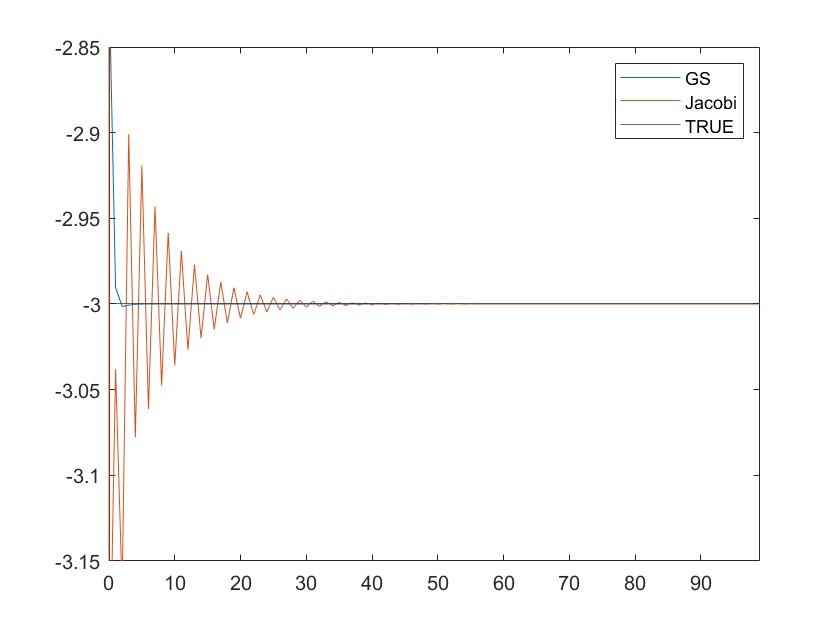



A = [7 1 3 2; 2 5 1 1; 4 3 10 2; 1 8 2 12];
b = [6; -4; 15; -39];
xTRUE = A\b;
x0 = zeros(4,1);
tol = 10^-8;
itMax = 99;
i=0;
base = 2;
J_DATA = zeros(length(A),100+2);
GS_DATA =  zeros(length(A),100+2);
J_ITERS = zeros(1,100+2);
GS_ITERS = zeros(1,100+2);

for i=0:itMax
    [conv, x1,j_iters] = myJacobi(A,b,x0,tol,1);
    if conv== 1
        break
    end
    J_DATA(:,i+2) = x1;
    J_ITERS(i+2) = i;
    
    x0=x1;
    
end
x0 = zeros(4,1);

for i=0:itMax/2
    [conv, x1,gs_iters] = myGS(A,b,x0,tol,1);
    GS_DATA(:,i+2) = x1;
    GS_ITERS(i+2) = i;
    x0=x1;
    
end
j_end_point = find(J_DATA(1,:)==0);
j_end_point = j_end_point(2)-1;
gs_end_point = find(GS_DATA(1,:)==0);
gs_end_point = gs_end_point(2)-1;



SHOW = 4;



plot(GS_ITERS(1:gs_end_point),GS_DATA(SHOW,1:gs_end_point));
hold on
plot(J_ITERS(1:j_end_point),J_DATA(SHOW,1:j_end_point));
hold on

yline(xTRUE(SHOW))
legend('GS','Jacobi', 'TRUE')
xlim([0 J_ITERS(j_end_point)])
ylim([xTRUE(SHOW)-.15 xTRUE(SHOW)+.15])
hold off

## Conclusion

At this point, you have been introduced to the Jacobi and Gauss-Seidel methods. You have seen their main strength; compared to Gaussian Elimination, our two iterative methods have superior run times. At the same time, our two iterative methods also have faults of their own. For one, as we briefly mentioned, neither method guarantees us a usable results. For another, while our methods are quicker than GE, faster methods exist, such as the Successive Over Relaxation (SOR) method, or the Conjugate Gradient (CG) method. While the use of the Jacobi and Gauss-Seidel methods are today strictly academic, we believe examining these two methods is still a worthwhile endeavor, as an understanding of the Jacobi and GS methods provides a good starting point for examining iterative methods in general. For more information on the covergence of the Jacobi and GS methods, we refer the interested reader to our paper, as well as to [2], David Strong's "Iterative Methods for Solving Ax = b". For more information on other iterative methods, such as SOR, we refer the interested reader to [3], *Matrix Iterative Methods*, by Richard S. Varga, and to chapter 20 of [1], *Numerical Linear Algebra with Applications Using Matlab*, by William Ford.

## References

 

 

 

## Appendix

myJacobi function (an implementation of the Jacobi method in MATLAB)

myGS function (an implementation of the Gauss-Seidel method in MATLAB)